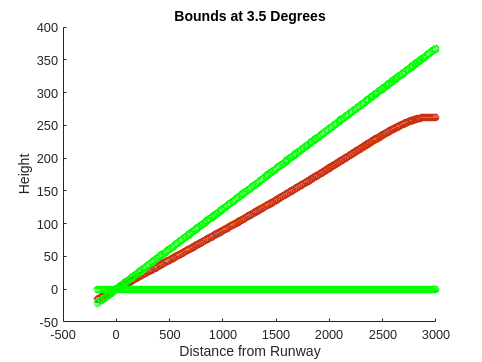

clear variables; close all; clc;
data = readtable("/home/achadbo/Desktop/Autoland/7-11-2024/3000/Gamma5_LatDev50/states.csv");
x = data.x;
h = data.h - 376;
y = data.y;
data_len = length(x);

data2 = readtable("/home/achadbo/Desktop/Autoland/7-11-2024/3000/Gamma5_LatDev100/states.csv");
x2 = data2.x;
h2 = data2.h - 376;
y2 = data2.y;

data3 = readtable("/home/achadbo/Desktop/Autoland/7-11-2024/3000/Gamma5_LatDev25/states.csv");
x3 = data3.x;
h3 = data3.h - 376;
y3 = data3.y;


bounds_color = "green";
three_half_color = [0.122, 0.439, 0.839];
five_color = [1 0.62 0];
ten_color = [0.8, 0.188, 0.078];

slope = tand(3.5);
slope_x = x.*slope;

r = slope * sqrt(x.^2 + slope_x.^2);
u_bounds = slope_x + r;
l_bounds = slope_x - r;

in_bound_rows = find(h <= u_bounds & h >= l_bounds & y <= r & y >= -r);
in_bound_data = data(in_bound_rows, ["x", "y", "h"]);
x_in = in_bound_data.x;
y_in = in_bound_data.y;
h_in = in_bound_data.h - 376;

scatter(x, h, 30, three_half_color);
hold on;
%scatter(x_in, h_in);
scatter(x2, h2, 30, five_color);
scatter(x3, h3, 30, ten_color);
scatter(x, u_bounds, 30, bounds_color);
scatter(x, l_bounds, 30, bounds_color);
xlabel("Distance from Runway");
ylabel("Height");
title("Bounds at 3.5 Degrees");
hold off;

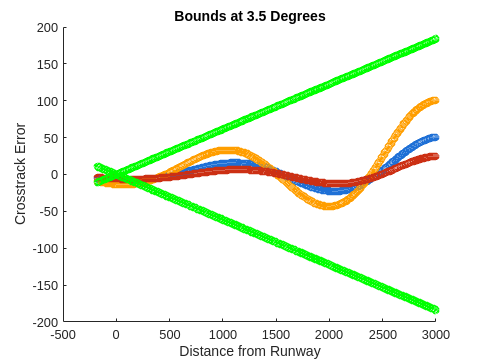


scatter(x, y, 30, three_half_color);
hold on;
% scatter(x_in, y_in);
scatter(x2, y2, 30, five_color);
scatter(x3, y3, 30, ten_color);
scatter(x, r, 30, bounds_color);
scatter(x, -r, 30, bounds_color);
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
title("Bounds at 3.5 Degrees");
hold off;

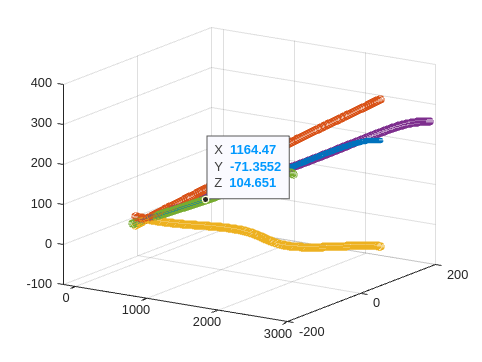


green = [0.4660 0.6740 0.1880];
blue = [0 0.4470 0.7410];
scatter3(x, y, h, 15, blue);
hold on;
scatter3(x, y, u_bounds);
scatter3(x, y, l_bounds);
scatter3(x, r, h);
scatter3(x, -r, h);

% scatter3(x_in, y_in, h_in, 50, green, "filled");
% xlabel("Distance from Runway");
% ylabel("Crosstrack Error");
% zlabel("Height");
% legend({"Out of Bounds", "In Bounds"}, 'Location', 'northwest');
% hold off;

